# Removing independent noise from functional brain microscopy data with a Deep Interpolation AI model

This example imports and applies a pretrained AI model using the DeepInterpolation concept[1] into MATLAB to denoise a small snippet of time-series microscopy image data representing live neural function.

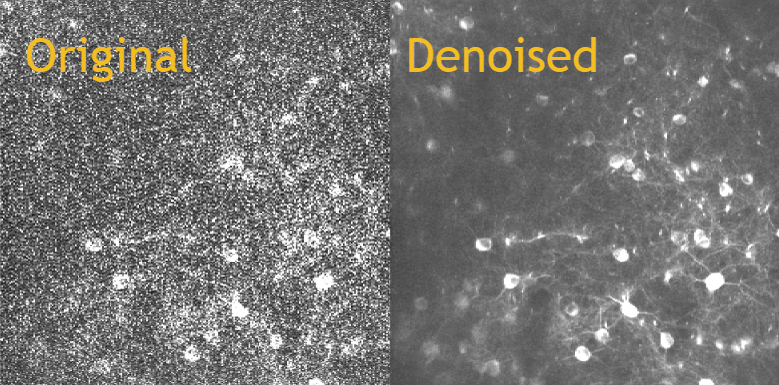

## About the AI Model & Sample Data

The DeepInterpolation originators' reference code implementation in Python[2] provides links to a set of cloud-hosted pretrained AI models, each trained on a specific experimental modality and configuration. This example uses the *Two-photon Ai93 excitatory line *pretrained model (120MB) trained on calcium imaging data of live excitatory neurons expressing a calcium indicator and collected with a two-photon microscope. It denoises the *tiny_ophys* sample data (included directly with [2]) which contains substantially similar data. 

## Pipeline Preview

This example will step through the following top-level pipeline steps:

- Import the image time-series sample data (TIFF volume)

- Import the pretrained model (DeepInterpolation concept)

- Configure the model processing pipeline

- Preprocess image time-series data

- Denoise data with DeepInterpolation concept

- Postprocess and visualize denoising results

See the [Outline panel](https://www.mathworks.com/help/matlab/matlab_prog/edit-and-format-code.html#mw_e5629e25-311d-433f-a064-8b11516d5a1e) for more granular section-by-section components. 

exampleInfo = setupExample(); % Download model & sample data & setup environment, and return example metadata

## Import the image time-series sample data (TIFF volume)

ophys = single(tiffreadVolume('ophys_tiny_761605196.tif'));
size(ophys)

ans =    512   512   100


The TIFF volume sample data is a time-series image stack with 100 timesteps each covering an area spanned by 512 by 512 pixels. 

### Inspect noise level of raw data

By viewing a few frames we can get a sense of the noise level of the input data: 

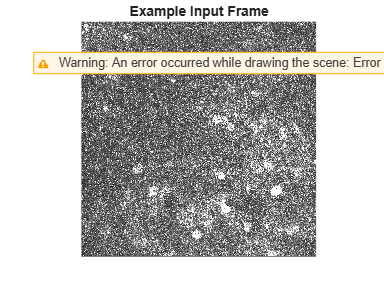

sliceIndex = 50;
imshow(ophys(:,:,sliceIndex), [0 prctile(ophys(:),95)])
title("Example Input Frame")

Whichever frame is inspected, the high level of independent noise significantly obscures the details near the neurons, whose cell bodies (somata) are visible as bright spots of approximately 100 square pixels. 

## Import the pretrained model (DeepInterpolation concept)

The original pretrained model is in a TensorFlow-Keras network format, which can be [imported into MATLAB](https://www.mathworks.com/help/deeplearning/ref/importkerasnetwork.html) but is no longer recommended. Therefore the model was converted to a TensorFlow file folder format using a Python script, and compressed into a ZIP file and stored in the cloud. This ZIP file was downloaded during example setup:

exampleInfo.modelZipFile

ans = '/MATLAB Drive/Repositories/DeepInterpolation-MATLAB-2/pretrainedModels/TensorFlowNetworks/TF_2019_09_11_23_32_unet_single_1024_mean_absolute_error_Ai93-0450.zip'

This ZIP file was also automatically unzipped during example setup, showing the Tensorflow folder structure of a model, including metadata from the original Tensorflow-Keras network:

dir(exampleInfo.modelFolder)


.                  ..                 assets             keras_metadata.pb  saved_model.pb     variables          



The function [`importNetworkFromTensorFlow`](https://www.mathworks.com/help/deeplearning/ref/importnetworkfromtensorflow.html?websocket=on)  imports the contents from the TensorFlow folder contents into the [`dlnetwork`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.html) format used by Deep Learning Toolbox:

importednet = importNetworkFromTensorFlow(exampleInfo.modelFolder, Namespace='trainedModel');

Importing the saved model...
Translating the model, this may take a few minutes...


Finished translation. Assembling network...
Import finished.


### Inspect the Network

The function [`analyzeNetwork`](https://www.mathworks.com/help/deeplearning/ref/analyzenetwork.html) can be used to visualize and understand the architecture of this pretrained network built on the DeepInterpolation concept: 

netInfo = analyzeNetwork(importednet);

The imported network shows layers of downsampling followed by upsampling as described in the originators' publication[1]. 

The first layer of the network indicates the input size of data the pretrained model expects, which is saved here for later use: 

inputSize = importednet.Layers(1).InputSize

inputSize =    512   512    60


The model expects input frames of 512 by 512 pixels, matched to the sample data frame size found above. It also has a "time window" size of 60 frames, which is shorter than the sample data length of 100 frames. 

## Preprocess data 

### Normalization of frames

[ophys, C, S] = normalize(ophys,3,"center","mean","scale","std"); % where C and S are centering and scaling values, respectively 

## **Configure the model inference pipeline**

Models based on the DeepInterpolation concept are intended to be applied to time-series of 2-D spatial (image) data. In these next code sections, the model processing pipeline is configured, specifying how the the pretrained model will be applied to the sample data for inference (denoising). 

### **Choose the number of frames to be omitted before and after the predicted frame**

The DeepInterpolation publication[1] directs the model trainer should omit one or a set of image frames from its input data, allowing the model to predict the omitted frames (from surround noisy frames) while minimizing the difference with the actual data introduced during training. During model inference, this "omitted block" parameter of the processing pipeline is not needed. 

pre_post_omission = 0; % omitted frame(s) not used during inference

### **Choose which frame to predict**

Select the center image frame on which to run inference with the DeepInterpolation processing pipeline:

target_frame = ceil(60); 

## **Denoise image time-series data using a DeepInterpolation model**

This example will use the [`predict`](https://www.mathworks.com/help/deeplearning/ref/dlnetwork.predict.html) function in Deep Learning Toolbox to apply the DeepInterpolation pretrained model to the sample data input. The application of deep learning models to achieve their trained function - in this case, removal of independent noise - is also referred to as *inference*. 

### Drop the omitted frames before prediction

Make prediction with the equivalent sized input:

pre_frame = 30; % Fixed number of frames before the predicted frame
post_frame = 30; % Fixed ber of frames after the predicted frame

This code section contains the generalized (for both training and inference) preprocessing of input data before being input to the DeepInterpolation AI model: 

input_index = (target_frame - pre_frame - pre_post_omission) : (target_frame + post_frame + pre_post_omission );
  
pre_post_omission_index = target_frame-pre_post_omission : target_frame+pre_post_omission; % index of frames to be dropped

for drop_frame = pre_post_omission_index
    input_index = input_index(input_index ~= drop_frame); % drop the predicted frame and the frames omitted before and after the predicted frame
end

### Perform inference with the DeepInterpolation model

ophysinterp = zeros(size(ophys));
offsets = -pre_frame:post_frame-1;

try
    for t = pre_frame+1 : size(ophys,3) - post_frame
	    ophysinterp(:,:,t) = predict(importednet,ophys(:,:,offsets+t));
    end
catch
    warning('Problem using predict.  Returning null.');
    ophysinterp = [];
end

## Postprocess and visualize denoising results

### Rescale normalized frames

ophys  = (ophys .* S) + C;
ophysinterp = (ophysinterp .* S) + C;

### Show denoising results

The denoising results can be shown again using `imshow `comparing input (raw) and output (denoised) frames. A `for` loop is used to show a time-series of raw and denoised frames, to reveal any signs of live brain function: 

for idx = 31:size(ophys,3)-30
    imshow([ophys(:,:,idx) ophysinterp(:,:,idx)],...
        [0 prctile(ophys(:),95)]);  % scaling image to 0 .. 95 percentile to show range
    pause(0.1);
end

Near the bottom center, one neuron becomes brighter indicating the cell has "fired" an action potential, and the signal can be seen to propagate along a neurite (axon or dendrite) extending towards the right. This can be seen much more clearly in the denoised image frames. 

## References

- Lecoq, J., Oliver, M., Siegle, J.H. *et al.* Removing independent noise in systems neuroscience data using DeepInterpolation. *Nat Methods* **18**, 1401–1408 (2021). [https://doi.org/10.1038/s41592-021-01285-2](https://doi.org/10.1038/s41592-021-01285-2)

- https://github.com/AllenInstitute/deepinterpolation

## Helper Functions

function exampleInfo = setupExample()

exampleInfo.baseFolder = deepinterp.setup();
exampleInfo.modelZipFile = deepinterp.internal.getPretrainedModelFilename('TP-Ai93-450');

[p,f,~] = fileparts(exampleInfo.modelZipFile);
exampleInfo.modelRootFolder = p; % extract root folder of model ZIP file, to which its which its contents will be extracted 

unzip(exampleInfo.modelZipFile,exampleInfo.modelRootFolder); % unzip model contents into same root folder
exampleInfo.modelFolder = fullfile(p,f); % store path to folder containing extracted contents; this is the TensorFlow model

end
